# Script to compute the GMT rejection TF

## Load telescope transfer functions

Load telescope transfer funcion computed a priori using script [compute_m1fan_rtf.mlx](matlab:open('./compute_m1fan_rtf.mlx')).

try
    load('M1S1fanTF_20210315_1728_lockedMNT_woM1ctrl.mat','G_fr');
    w = G_fr.Frequency;
catch ME
    warning('Unable to load telescope transfer function files!') 
end


Apply NS or LTAO RTF

rtf(1:14,1:14) = eye(14)*frd(oad_NS_rtf(w),w);
rtf(15:21,15:21) = eye(7)*frd(tf(1,1),w);
Gf_NSrtf_fr = rtf * G_fr;

rtf(1:14,1:14) = eye(14)*frd(oad_AOTT_rtf(w),w);
rtf(15:21,15:21) = eye(7)*frd(getRTF_DP(w),w);
Gf_AOrtf_fr = rtf * G_fr;

## Plot vibration transfer functions (TFs)

plotOutLabel = {'F_x','F_y','F_z','M_x','M_y','M_z'};
plotUnitstr = {'N','N','N','Nm','Nm','Nm'};
reposFIGs = [1,3,5,2,4,6];
if(~exist('m1_FBc','var')), m1_FBc = 0; end

### NS-Rx

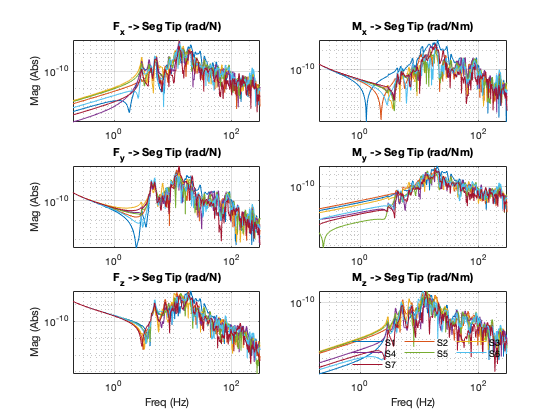

figure(11+3*m1_FBc);
set(gcf,'Name','FRF mag - M1 FAN to Seg Tip');
for i2 = 1:6    
    subplot(3,2,reposFIGs(i2));
    loglog(w/2/pi, squeeze(abs(Gf_NSrtf_fr.ResponseData(1:7,i2,:))));
    xlim([min(w/2/pi),max(w/2/pi)]);
    
    title(sprintf('%s -> Seg Tip (rad/%s)',plotOutLabel{i2},plotUnitstr{i2}));
    if(reposFIGs(i2) >= 5), xlabel('Freq (Hz)'); end
    if(mod(reposFIGs(i2),2)), ylabel('Mag (Abs)'); end
    grid on;
end
legend('S1','S2','S3','S4','S5','S6','S7','NumColumns',3,'Orientation',"horizontal",'Location','Best');
legend boxoff;

### NS-Ry

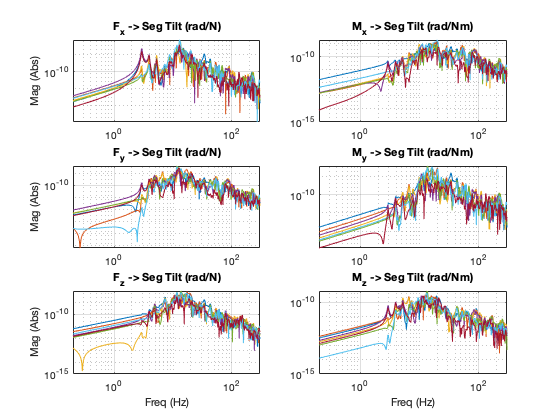

figure(12+3*m1_FBc);
set(gcf,'Name','FRF mag - M1 FAN to Seg Tilt');
for i2 = 1:6    
    subplot(3,2,reposFIGs(i2));
    loglog(w/2/pi, squeeze(abs(Gf_NSrtf_fr.ResponseData(8:14,i2,:))));
    xlim([min(w/2/pi),max(w/2/pi)]);
    
    title(sprintf('%s -> Seg Tilt (rad/%s)',plotOutLabel{i2},plotUnitstr{i2}));
    if(reposFIGs(i2) >= 5), xlabel('Freq (Hz)'); end
    if(mod(reposFIGs(i2),2)), ylabel('Mag (Abs)'); end
    grid on;
end

### NS-Piston

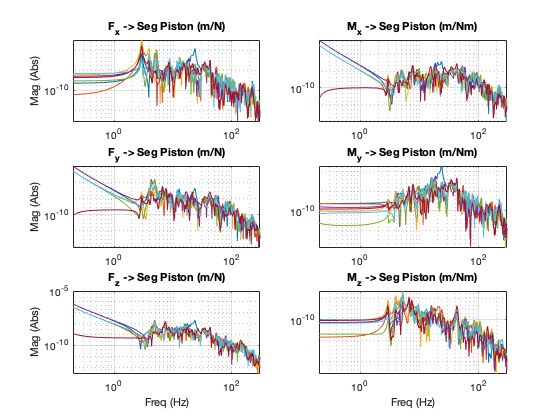

figure(13+3*m1_FBc);
set(gcf,'Name','FRF mag - M1 FAN to Seg Piston');
for i2 = 1:6    
    subplot(3,2,reposFIGs(i2));
    loglog(w/2/pi, squeeze(abs(Gf_NSrtf_fr.ResponseData(15:21,i2,:))));
    xlim([min(w/2/pi),max(w/2/pi)]);
    
    title(sprintf('%s -> Seg Piston (m/%s)',plotOutLabel{i2},plotUnitstr{i2}));
    if(reposFIGs(i2) >= 5), xlabel('Freq (Hz)'); end
    if(mod(reposFIGs(i2),2)), ylabel('Mag (Abs)'); end
    grid on;
end

### AO-Rx

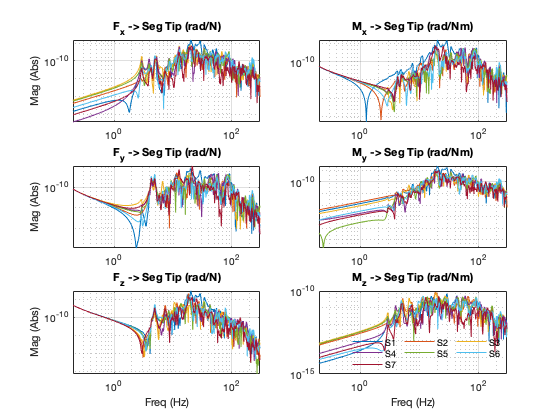

figure(14+3*m1_FBc);
set(gcf,'Name','FRF mag - M1 FAN to Seg Tip');
for i2 = 1:6    
    subplot(3,2,reposFIGs(i2));
    loglog(w/2/pi, squeeze(abs(Gf_AOrtf_fr.ResponseData(1:7,i2,:))));
    xlim([min(w/2/pi),max(w/2/pi)]);
    
    title(sprintf('%s -> Seg Tip (rad/%s)',plotOutLabel{i2},plotUnitstr{i2}));
    if(reposFIGs(i2) >= 5), xlabel('Freq (Hz)'); end
    if(mod(reposFIGs(i2),2)), ylabel('Mag (Abs)'); end
    grid on;
end
legend('S1','S2','S3','S4','S5','S6','S7','NumColumns',3,'Orientation',"horizontal",'Location','Best');
legend boxoff;

### AO-Ry

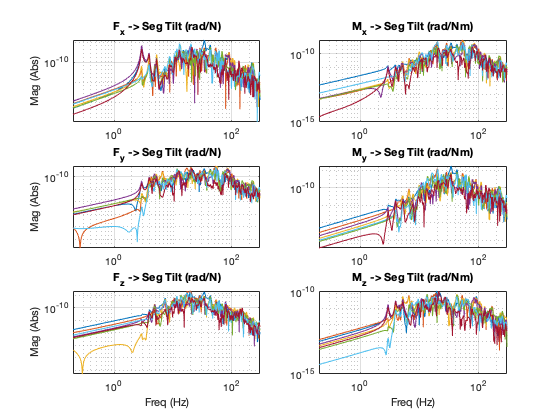

figure(15+3*m1_FBc);
set(gcf,'Name','FRF mag - M1 FAN to Seg Tilt');
for i2 = 1:6    
    subplot(3,2,reposFIGs(i2));
    loglog(w/2/pi, squeeze(abs(Gf_AOrtf_fr.ResponseData(8:14,i2,:))));
    xlim([min(w/2/pi),max(w/2/pi)]);
    
    title(sprintf('%s -> Seg Tilt (rad/%s)',plotOutLabel{i2},plotUnitstr{i2}));
    if(reposFIGs(i2) >= 5), xlabel('Freq (Hz)'); end
    if(mod(reposFIGs(i2),2)), ylabel('Mag (Abs)'); end
    grid on;
end

### AO-Piston

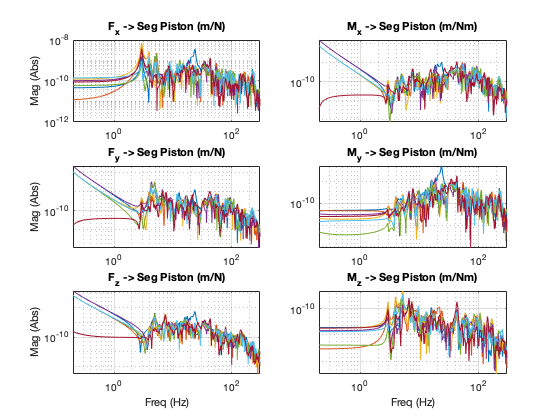

figure(16+3*m1_FBc);
set(gcf,'Name','FRF mag - M1 FAN to Seg Piston');
for i2 = 1:6    
    subplot(3,2,reposFIGs(i2));
    loglog(w/2/pi, squeeze(abs(Gf_AOrtf_fr.ResponseData(15:21,i2,:))));
    xlim([min(w/2/pi),max(w/2/pi)]);
    
    title(sprintf('%s -> Seg Piston (m/%s)',plotOutLabel{i2},plotUnitstr{i2}));
    if(reposFIGs(i2) >= 5), xlabel('Freq (Hz)'); end
    if(mod(reposFIGs(i2),2)), ylabel('Mag (Abs)'); end
    grid on;
end

## Rejection transfer functions (RTFs)

Function to compute the NS RTF (according to REQ-L3-OAD-35337)

function [rtf,L] = oad_NS_rtf(w)

% PZT closed-loop bandwidth (Hz)
fz = 25;
% PZT control loop damping
delta = 0.6;
% TT loop sampling period
T = 5e-3;
% TT sensor delay
tau = 6e-3;
% TT "integral gain" - actually the considered integral gain is gi/T
gi = 0.3;

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the GLAO RTF (according to REQ-L3-OAD-35398)

function [rtf,L] = oad_AOTT_rtf(w)

% LTAO RTF (according to REQ-L3-OAD-35398)
fz = 800;       % ASM closed-loop bandwidth (Hz)
delta = 0.75;   % ASM control loop damping
T = 2e-3;   % TT loop sampling period
tau = 1e-3; % TT sensor delay
gi = 0.4;   % TT "integral gain"

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
L = exp(-tau*s) .* (1-exp(-T*s))./(T*s) .* (gi/T./s) .*...
    (omz^2)./((omz^2)+2*omz*delta*s+(s.^2));

rtf = 1./(1 + L);

end

Function to compute the differential piston RTF

function RTF_DP = getRTF_DP(om)
    
s = sqrt(-1)*om;

%% FROM DRD rev F
omz = 800*2*pi;
dz = .75;
Tp = 30;
taup= 6/1000;
gpi = .5;
Te = 2/1000;
taue = .1/1000;
geff = .8;

num = 1 + omz^2*geff*exp(-taue*s).*(exp(-Te*s)-1)./(Te*s.*    (omz^2+2*omz*dz*s+s.^2) );
den = 1 - omz^2*gpi*exp(-taup*s).*(exp(-Tp*s)-1)./(Tp^2*s.^2.*(omz^2+2*omz*dz*s+s.^2) );
RTF_DP = num./den;
    
    
end